close all
clear all
N=100000;
x=rand(N,3)*2*pi-pi;
y=ishigamifunction(x);
fitlm(x,y)

ans = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate        SE         tStat     pValue 
                   _________    _________    _______    _______

    (Intercept)       3.5058     0.010578     331.43          0
    x1               0.89258    0.0058337        153          0
    x2             -0.006695    0.0058289    -1.1486    0.25073
    x3              0.014978    0.0058364     2.5663    0.01028


Number of observations: 100000, Error degrees of freedom: 99996
Root Mean Squared Error: 3.34
R-squared: 0.19,  Adjusted R-Squared: 0.19
F-statistic vs. constant model: 7.81e+03, p-value = 0

%%
[d,Si]=deltamim(x,y,20);
for i=1:3
    aa=corrcoef(x(:,i),y);
    rho(i)=aa(1,2);
end
subplot(2,1,1)
bar(rho);
labels={'$X_1$','$X_2$','$X_3$'}

labels = 1×3 cell array
    {'$X_1$'}    {'$X_2$'}    {'$X_3$'}


ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
set(gca,'Fontsize',24)
xticklabels(labels)
title('Pearson Correlation Coefficient')
ylabel('$\rho(Y,X_i)$','Interpreter','latex')
subplot(2,1,2)
bar(Si);
labels={'$X_1$','$X_2$','$X_3$'}

labels = 1×3 cell array
    {'$X_1$'}    {'$X_2$'}    {'$X_3$'}


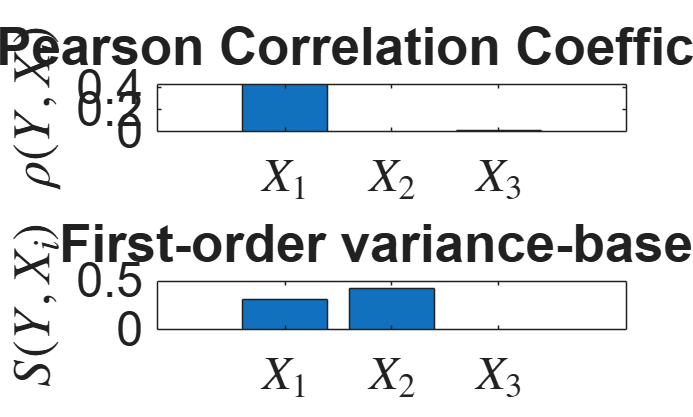

ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
set(gca,'Fontsize',24)
xticklabels(labels)
title('First-order variance-based')
ylabel('$S(Y,X_i)$','Interpreter','latex')

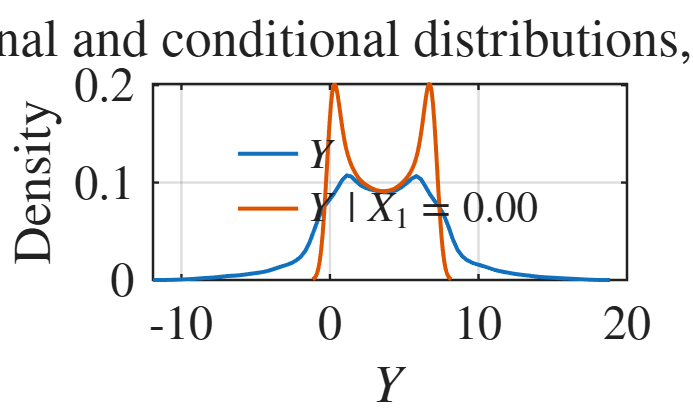


%% Learning an input: conditional distribution of Y given X_i = x_i^*

% Choose which input to condition on
i_cond = 1;              % 1, 2, or 3

% Choose the value of X_i
x_cond = 0;              % for example: 0, pi/2, -pi/2, etc.

% Construct a conditional input sample
x_conditional = x;

% Replace the chosen column by the fixed value
x_conditional(:,i_cond) = x_cond;

% Recompute the model output under the condition X_i = x_i^*
y_conditional = ishigamifunction(x_conditional);

% Kernel density estimates
[f_marg, y_grid_marg] = ksdensity(y);
[f_cond, y_grid_cond] = ksdensity(y_conditional);

% Plot marginal and conditional densities
figure

plot(y_grid_marg, f_marg, 'LineWidth',2)
hold on
plot(y_grid_cond, f_cond, 'LineWidth',2)

grid on
box on

xlabel('$Y$','Interpreter','latex')
ylabel('Density','Interpreter','latex')

title(sprintf('Marginal and conditional distributions, $X_%d = %.2f$', ...
    i_cond, x_cond), ...
    'Interpreter','latex')

legend({ ...
    '$Y$', ...
    sprintf('$Y\\mid X_%d = %.2f$', i_cond, x_cond)}, ...
    'Interpreter','latex', ...
    'Location','best', ...
    'Box','off');

set(gca, ...
    'TickLabelInterpreter','latex', ...
    'FontSize',24, ...
    'LineWidth',1.2);

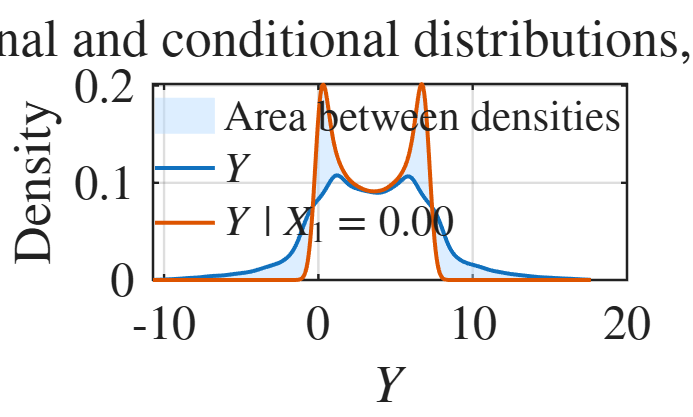


%%
%% Learning an input: conditional distribution of Y given X_i = x_i^*

% Choose which input to condition on
i_cond = 1;              % 1, 2, or 3

% Choose the value of X_i
x_cond = 0;              % for example: 0, pi/2, -pi/2, etc.

% Construct a conditional input sample
x_conditional = x;

% Replace the chosen column by the fixed value
x_conditional(:,i_cond) = x_cond;

% Recompute the model output under the condition X_i = x_i^*
y_conditional = ishigamifunction(x_conditional);

% Common grid for the two densities
y_min = min([y; y_conditional]);
y_max = max([y; y_conditional]);
y_grid = linspace(y_min, y_max, 500);

% Kernel density estimates on the same grid
f_marg = ksdensity(y, y_grid);
f_cond = ksdensity(y_conditional, y_grid);

% Plot
figure
hold on

% Light blue shaded area between the two densities
fill([y_grid fliplr(y_grid)], ...
    [f_marg fliplr(f_cond)], ...
    [0.70 0.85 1.00], ...
    'EdgeColor','none', ...
    'FaceAlpha',0.45);

% Density curves
plot(y_grid, f_marg, 'LineWidth',2)
plot(y_grid, f_cond, 'LineWidth',2)

grid on
box on

xlabel('$Y$','Interpreter','latex')
ylabel('Density','Interpreter','latex')

title(sprintf('Marginal and conditional distributions, $X_%d = %.2f$', ...
    i_cond, x_cond), ...
    'Interpreter','latex')

legend({ ...
    'Area between densities', ...
    '$Y$', ...
    sprintf('$Y\\mid X_%d = %.2f$', i_cond, x_cond)}, ...
    'Interpreter','latex', ...
    'Location','best', ...
    'Box','off');

set(gca, ...
    'TickLabelInterpreter','latex', ...
    'FontSize',24, ...
    'LineWidth',1.2);

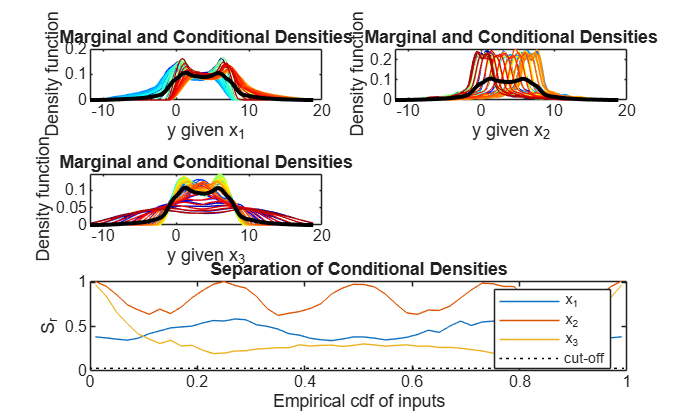

delta =     0.2235    0.4072    0.1762


Si =     0.3138    0.4395    0.0008


acceptL =     1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000
    1.0000    1.0000    0.9784


Seps =     0.3852    0.3728    0.3585    0.3476    0.3707    0.4201    0.4522    0.4857    0.4965    0.5055    0.5419    0.5685    0.5632    0.5861    0.5776    0.5210    0.5031    0.4724    0.4216    0.4039    0.3689    0.3521    0.3423    0.3604    0.3833    0.3834    0.3697    0.3504    0.3623    0.3801    0.4111    0.4599    0.4347    0.5051    0.5622    0.5133    0.5517    0.5619    0.5451    0.5435    0.5187    0.5357    0.4890    0.4425    0.4135    0.3840    0.3544    0.3604    0.3746    0.3850
    1.0079    0.9548    0.8577    0.7440    0.6876    0.6393    0.6967    0.6478    0.7217    0.8261    0.9075    0.9784    1.0073    0.9631    0.9344    0.8402    0.7035    0.6260    0.6502    0.6693    0.7041    0.7576    0.8686    0.9335    0.9765    0.9742    0.9464    0.8664    0.7539    0.6541    0.6382    0.6863    0.6823    0.7302    0.8229    0.9132    0.9891    0.9834    0.9533    0.9514    0.7936    0.7672    0.6619    0.6955    0.6824    0.7004    0.7452    0.8549    0.9520  

%%
[delta,Si,acceptL,Seps]=deltamim(x,y,50,'Marginal and Conditional Densities')

%%
figure
bar(d);
labels={'$X_1$','$X_2$','$X_3$'}

labels = 1×3 cell array
    {'$X_1$'}    {'$X_2$'}    {'$X_3$'}


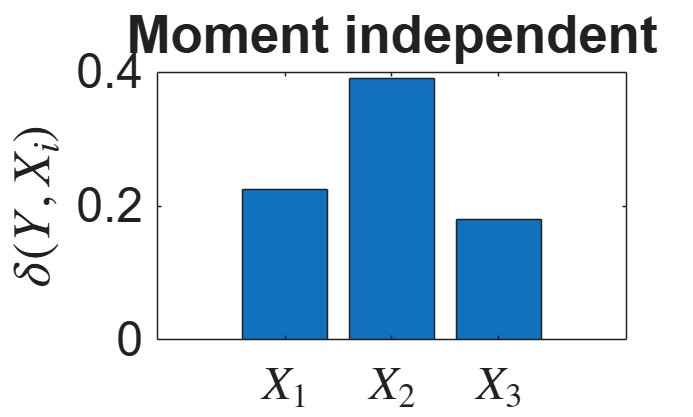

ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';

xticklabels(labels)
ylabel('$\delta(Y,X_i)$','Interpreter','latex')
title('Moment independent')
set(gca,'Fontsize',24)

%%
[W,d,nn]=wassersi(x,y,50);
figure
C=W.W22/(2*var(y));
bar(W.W22/(2*var(y)))
labels={'$X_1$','$X_2$','$X_3$'}

labels = 1×3 cell array
    {'$X_1$'}    {'$X_2$'}    {'$X_3$'}


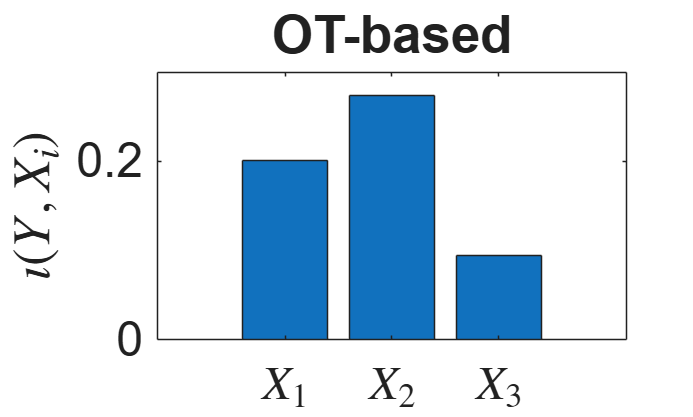

ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';

xticklabels(labels)
ylabel('$\iota(Y,X_i)$','Interpreter','latex')
title('OT-based')
set(gca,'Fontsize',24)

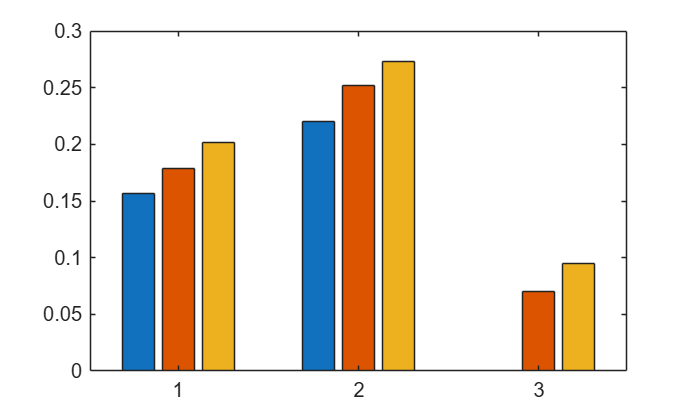


%%
[Wass2,WassSep,SinkSep,Mean2Sep]=bwsi(x,y,50);
%%
WB=mean(WassSep)./(2*var(y));
V2=mean(Mean2Sep)./(2*var(y));
A=[V2; WB; C];
figure
bar(A')


%%
figure
A=[V2; WB; C];
figure
b=bar(A')

b =   1×3 Bar array:

    Bar    Bar    Bar


%b.FaceColor = 'flat';
cols = [
    0.0000 0.2000 0.8000   % stronger blue
    1.0000 0.0000 0.0000   % true red
    1.0000 0.8000 0.0000   % shiny yellow
    ];

for k = 1:numel(b)
    b(k).FaceColor = cols(k,:);
end

legend({'$S(Y,X_i)$','$WB(Y,X_i)$','$\iota(Y,X_i)$'}, ...
    'Interpreter','latex', ...
    'Location','best', ...
    'Box','off','FontSize',28);
labels={'$X_1$','$X_2$','$X_3$'}

labels = 1×3 cell array
    {'$X_1$'}    {'$X_2$'}    {'$X_3$'}


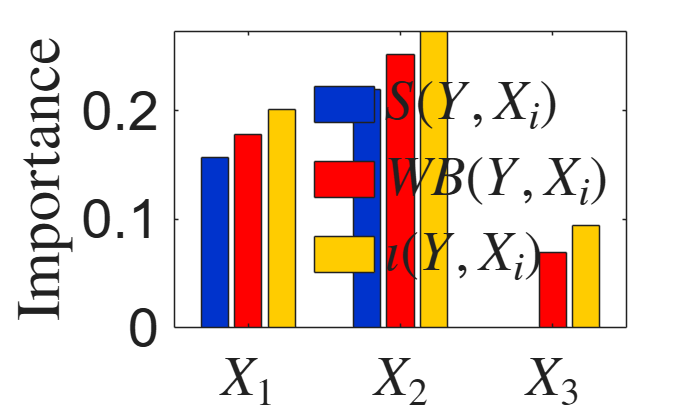

ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';

xticklabels(labels)
ylabel('Importance','Interpreter','latex')
set(gca,'FontSize',28)